# Import GPX and calculate route distance

The steps to follow are:

- Search for a route in Google Maps.

- Download gpx with [https://mapstogpx.com/](https://mapstogpx.com/) and this configuration

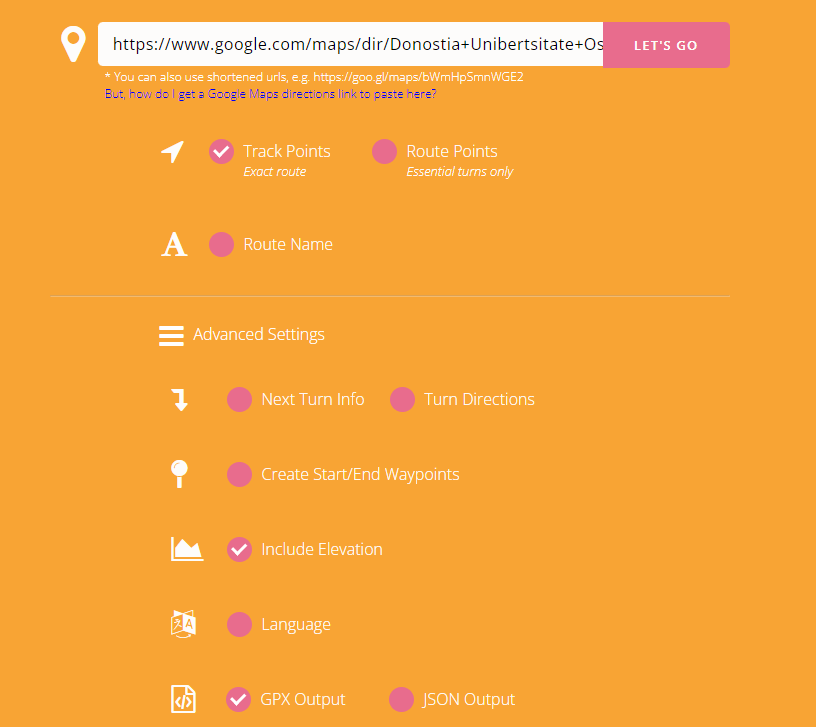

## Import route info from gpx file

clear all
p = gpxread('Errenteria2Donostia.gpx');

## Plot data

Plot elevation

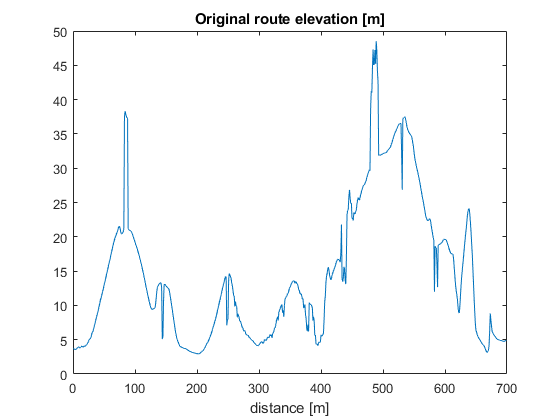

figure
plot(p.Elevation)
title('Original route elevation [m]')
xlabel('distance [m]')

Plot route in map

webmap('openstreetmap')
wmline(p)

## Preprocess data to remove outliers

It can be seen from the elevation plot that there are some outliers. The elevation changes dramatically in few meters.

We are going to smooth the elevation profile to avoid inconsistent estimates.

Elevation = p.Elevation;

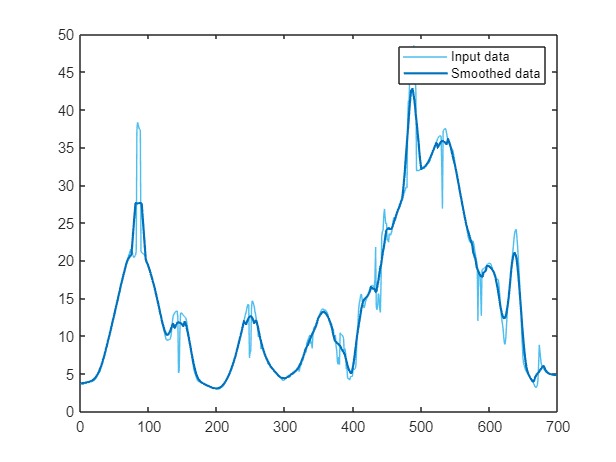

% Smooth input data
ElevationSmooth = smoothdata(Elevation,"movmean","SmoothingFactor",0.05);

% Display results
clf
plot(Elevation,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(ElevationSmooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

Latitude = p.Latitude;
Longitude = p.Longitude;

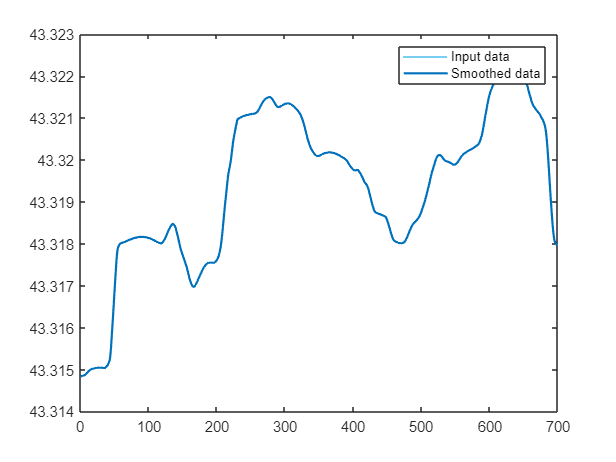

% Smooth input data
Latitude = smoothdata(Latitude,"movmean",10);

% Display results
clf
plot(Latitude,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(Latitude,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

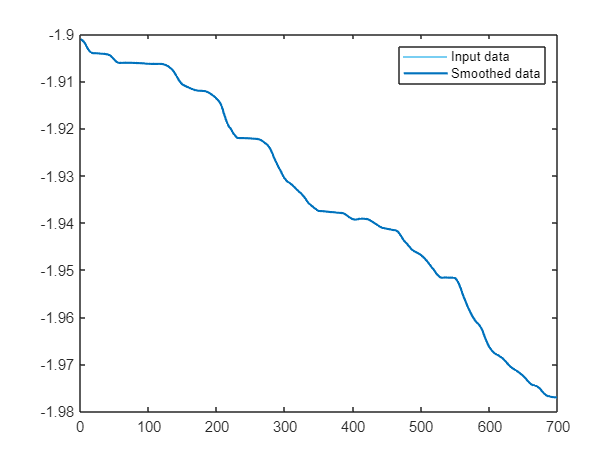

% Smooth input data
Longitude = smoothdata(Longitude,"movmean",10);

% Display results
clf
plot(Longitude,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(Longitude,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

## Calculate distance using [haversine](https://en.wikipedia.org/wiki/Haversine_formula) function

delta_distance(1) = 0;
distance(1) = 0;
delta_elevation(1) = 0;
for i = 2:length(p.Latitude)
    % Obtain distance increments between coordinate points in meters
    delta_distance(i) = haversine([Latitude(i-1), Longitude(i-1)], [Latitude(i), Longitude(i)])*1000; % Haversine function gives distance in km
    % Obtain distance per coordinate points in meters
    distance(i) = distance(i-1) + delta_distance(i);
    delta_elevation(i) = ElevationSmooth(i) - ElevationSmooth(i-1);
end
% Obtain total distance in meters
total_distance = sum(delta_distance);
% Obtain total distance in kilometers
total_distance_km = sum(delta_distance)/1000

total_distance_km = 7.1959

## Plot elevation vs. distance

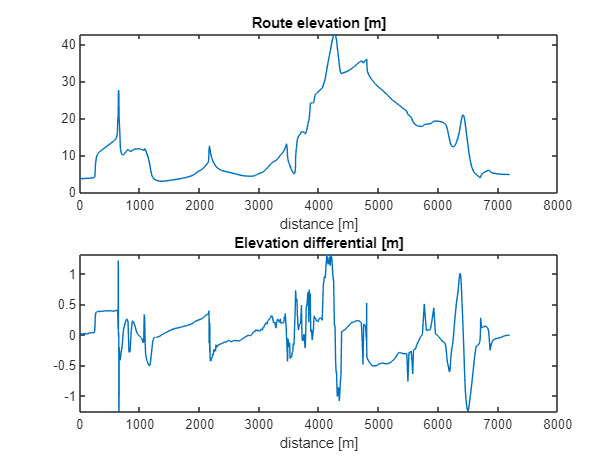

figure
subplot(211)
plot(distance',ElevationSmooth)
title('Route elevation [m]')
xlabel('distance [m]')

subplot(212)
plot(distance',delta_elevation)
title('Elevation differential [m]')
xlabel('distance [m]')

## Calculate elevation angle

angle = asin(delta_elevation./delta_distance);
angle(1) = 0;
figure
plot(distance',angle*180/pi)

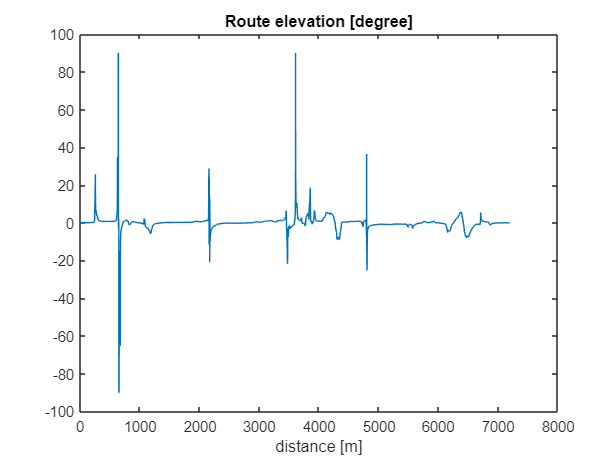

title('Route elevation [degree]')
xlabel('distance [m]')

## Save elevation and distance data

save Gros2Ulia distance Elevation angle total_distance